# Part 6: Problem set answers

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

[*Return to problem set*](matlab: edit S5_ProblemSet.mlx)

## Load and set up necessary data: 

filename = "penguins.csv";
penguins = readtable(filename);
penguins.species = categorical(penguins.species);

## Problem 1: 

Use the `pie()` function to make a chart that shows the percentage of males and females overall in this dataset. You will first need to use `categorical()` to make a categorical array of` penguins.sex`. 

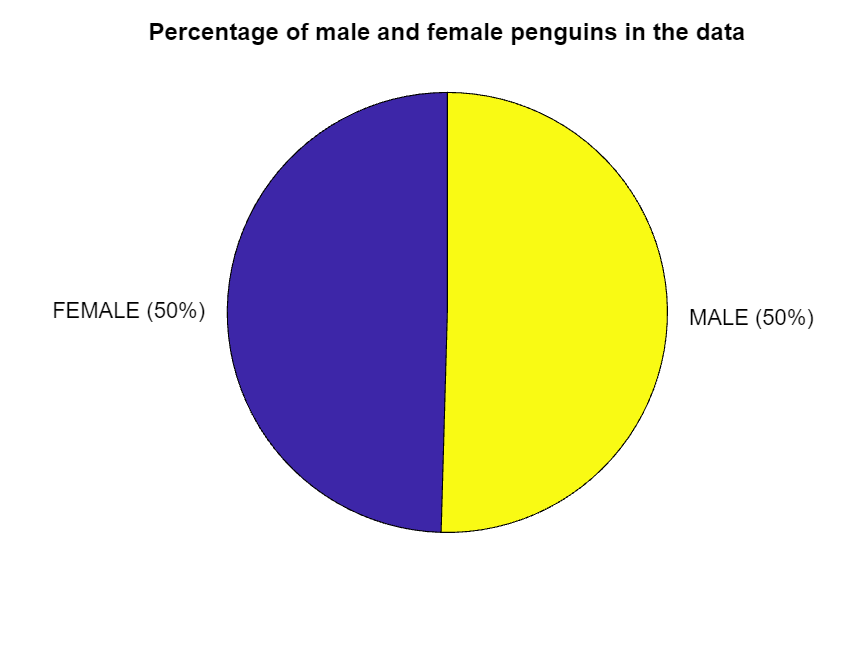

sex = categorical(penguins.sex);
pie(sex)
title ('Percentage of male and female penguins in the data')

 Students should notice that males and females are equally present in the collected data. This means that we can meaningfully compare males versus females- the data is not heavily skewed in either direction. 

## Problem 2: 

Create a scatter plot of bill depth versus body mass for all penguins. Include an x-label, y-label, and title:

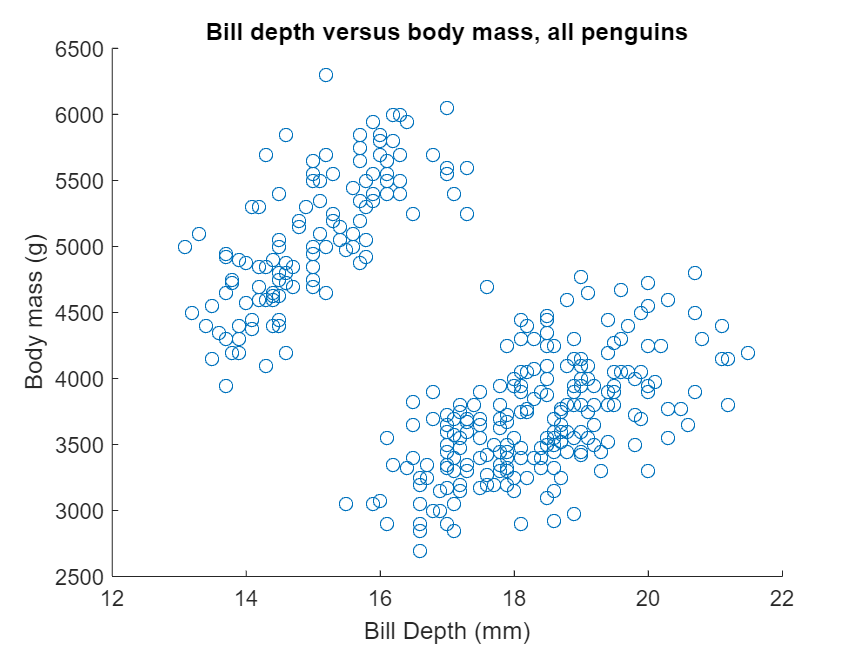

scatter (penguins.bill_depth_mm, penguins.body_mass_g)
xlabel ('Bill Depth (mm)')
ylabel ('Body mass (g)')
title ('Bill depth versus body mass, all penguins')

 Students should notice 2 distinct groups in this scatter plot. 

## Problem 3: 

Investigate what the cause of the distinct groups from Problem 2 might be. 

Use `gscatter()` to plot bill depth versus body mass grouped by sex. Include an x-label, y-label, and title:

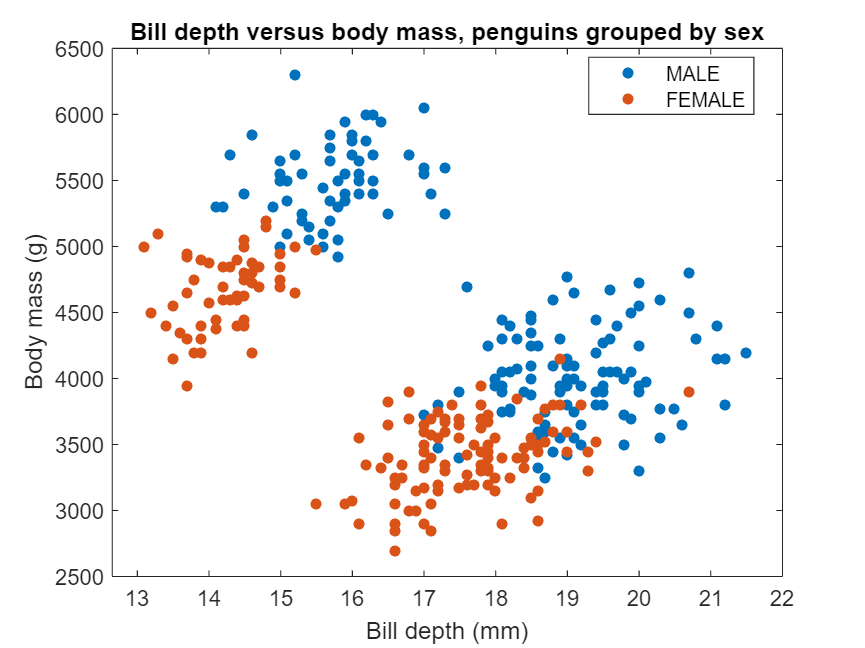

gscatter(penguins.bill_depth_mm, penguins.body_mass_g, penguins.sex)
xlabel('Bill depth (mm)')
ylabel('Body mass (g)')
title ('Bill depth versus body mass, penguins grouped by sex')

Use `gscatter()` again to plot bill depth versus body mass grouped by species:

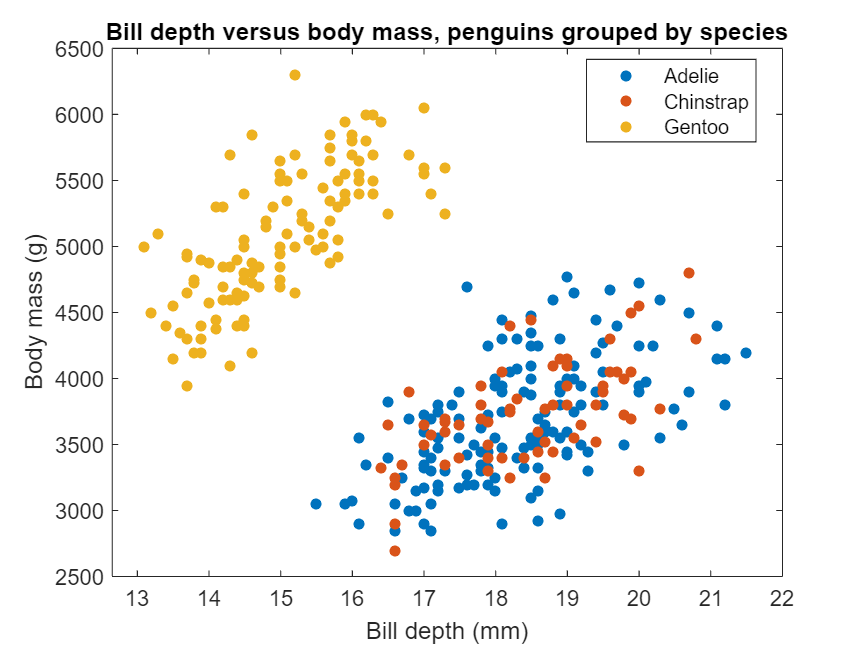

gscatter(penguins.bill_depth_mm, penguins.body_mass_g, penguins.species)
xlabel('Bill depth (mm)')
ylabel('Body mass (g)')
title('Bill depth versus body mass, penguins grouped by species')

  Student conclusions should be related to the fact that the bill depth v. body mass grouping is more dependent on species (whether the penguin is Gentoo or not, than sex, which is pretty evenly split among the groups we found in Problem 2)

***Bonus: ***Go back to your species graph and plot the species with different symbols.

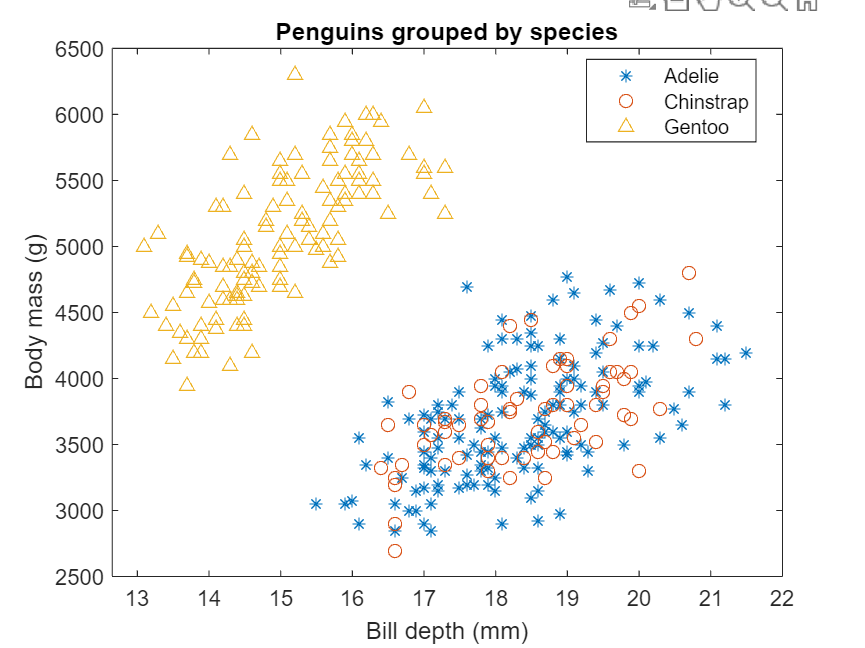

%BONUS 
symb= ['*','o', '^'];
gscatter(penguins.bill_depth_mm, penguins.body_mass_g, penguins.species, '', symb)
xlabel('Bill depth (mm)')
ylabel('Body mass (g)')
title('Bill depth versus body mass, penguins grouped by species')

[*Return to introduction*](matlab: edit S1_Introduction.mlx)